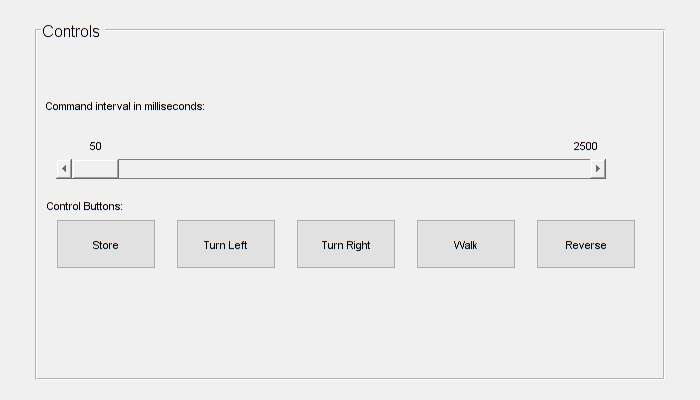

% Create a figure
f = figure('Name', 'Robot Control', 'NumberTitle', 'off');
% Adjust the figure size
f.Position(3) = 700; % Set the figure width
f.Position(4) = 400; % Set the figure height
% Create a uipanel within the figure
panel = uipanel(f, 'Title', 'Controls', 'FontSize', 12, 'Position', [.05 .05 .9 .9]);

% Create the slider
slider = uicontrol(panel, 'Style', 'slider', 'Min', 50, 'Max', 2500, 'Value', 50, 'Position', [20 200 550 20], 'Callback', {@slider_callback, f});
% Create a text label for Speed
valueLabel = uicontrol(panel, 'Style', 'text', 'Position', [-10 260 200 20], 'HorizontalAlignment', 'center', 'String', 'Command interval in milliseconds:');
% VariableSpeed = 50;
% valueLabelSpeed = uicontrol(panel, 'Style', 'text', 'Position', [160 260 20 20], 'HorizontalAlignment', 'center', 'String', num2str(VariableSpeed));
% Create a text label for displaying the value
valueLabel1 = uicontrol(panel, 'Style', 'text', 'Position', [10 220 100 20], 'HorizontalAlignment', 'center', 'String', num2str(get(slider, 'Value')));
% Create a text label for displaying the value
valueLabel2 = uicontrol(panel, 'Style', 'text', 'Position', [500 220 100 20], 'HorizontalAlignment', 'center', 'String', num2str(get(slider, 'Max')));

% Create a text label for Buttons
valueLabel3 = uicontrol(panel, 'Style', 'text', 'Position', [0 160 100 20], 'HorizontalAlignment', 'center', 'String', 'Control Buttons:');
% Create the buttons
btn1 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Store', 'Position', [20 110 100 50], 'Callback', {@store_callback, f});
btn2 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Turn Left', 'Position', [140 110 100 50], 'Callback', {@left_callback, f});
btn3 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Turn Right', 'Position', [260 110 100 50], 'Callback', {@right_callback, f});
btn4 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Walk', 'Position', [380 110 100 50], 'Callback', {@walk_callback, f});
btn5 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Reverse', 'Position', [500 110 100 50], 'Callback', {@reverse_callback, f});


% Connect to the serial port
s = serialport('COM6', 9600);

% Store s as a property of f
f.UserData = s;

% Callback functions

function store_callback(src, event, f)
    s = f.UserData;
    fprintf('Store button pressed.\n');
    write(s, 's', "char");
end

function right_callback(src, event, f)
    s = f.UserData;
    fprintf('Right button pressed.\n');
    write(s, 'r', "char");
end

function left_callback(src, event, f)
    s = f.UserData;
    fprintf('Left button pressed.\n');
    write(s, 'l', "char");
end

function walk_callback(src, event, f)
    s = f.UserData;
    fprintf('Walk button pressed.\n');
    write(s, 'w', "char");
end

function reverse_callback(src, event, f)
    s = f.UserData;
    fprintf('Reverse button pressed.\n');
    write(s, 'u', "char");
end

function slider_callback(src, event, f)
    s = f.UserData;
    speed = round(get(src, 'Value'));
    fprintf('Slider adjusted, speed: %d\n', speed);
    write(s, 'i', "char");
    write(s, speed, "int16");
end
